# EE 451 Homework 11

# Lisa Jacklin 

# Due 12/7/2023

## Problem 3 

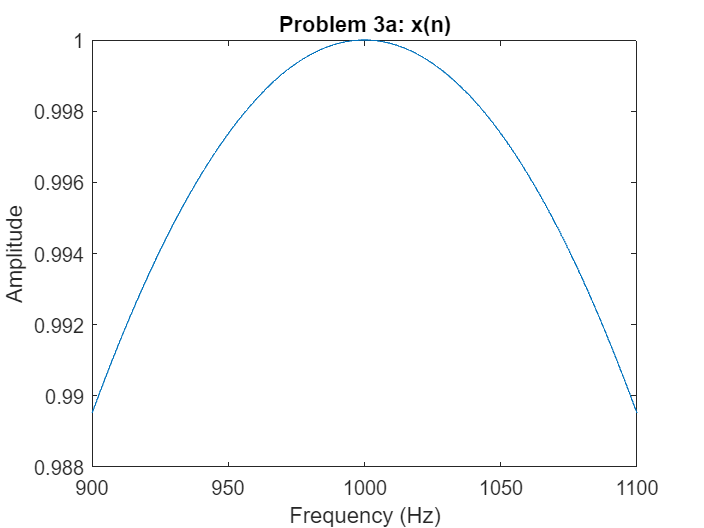

%we have xat which ranges from 900 to 1100 Hz bandlimited. Hw cutoff
%frequeny for the ideal lowpass filter is Fc = 125Hz.

%first we need to find xn
Fs = 2500; %this is the sampling rate from the A/D converter
Ts = 1/Fs; n = round(Ts*Fs);
f_low = 900; f_high = 1100;

% Define the frequency range
F = linspace(f_low, f_high, 1000);

% Create a bandlimited function using the sinc function
xtn = sinc((F - 1000) / (Fs/2));

% Plot the bandlimited function
plot(F, xtn);
title('Problem 3a: x(n)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

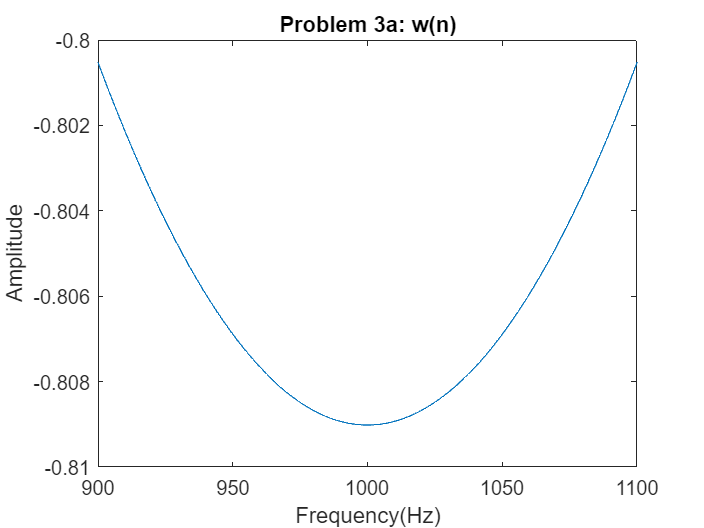


%need to find wn
%wn has the circular convolution of the equation with cos(0.8pin)
cros = cos(0.8*pi*n);
xw = cconv(xtn, cros);

plot(F, xw);
title("Problem 3a: w(n)");
xlabel("Frequency(Hz)");
ylabel("Amplitude");

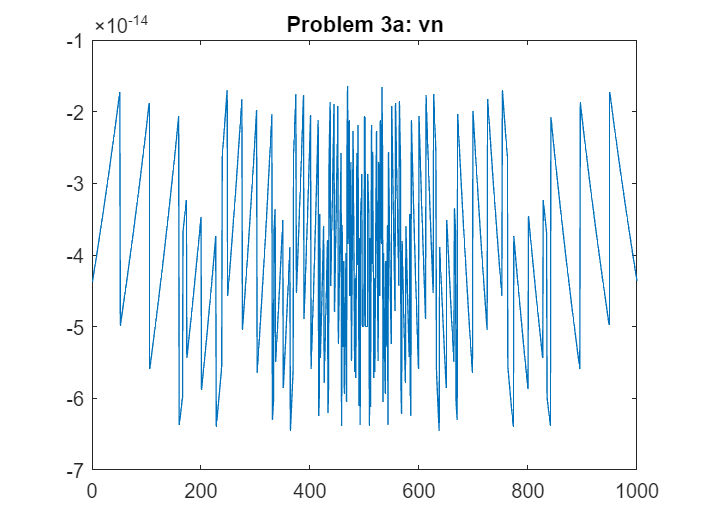


%now to find vn
%here, we need to add in the ldeal lowpass filter with a cutoff frequency
%at 125Hz
M = length(xw);
cutoff = 125 * 2 * pi;
%using function from class
Hw = ideal_lp(cutoff, M);
vn = Hw .* xw;
plot(vn);
title("Problem 3a: vn");

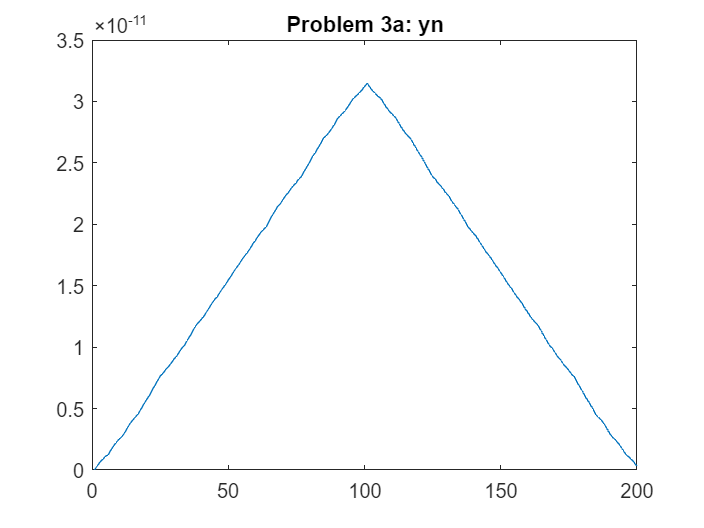

% and yn from the equation
% now, to set up a decimation by 10
D = 10;
yn = upfirdn(xw, vn, 1, D);

plot(yn);
title("Problem 3a: yn");

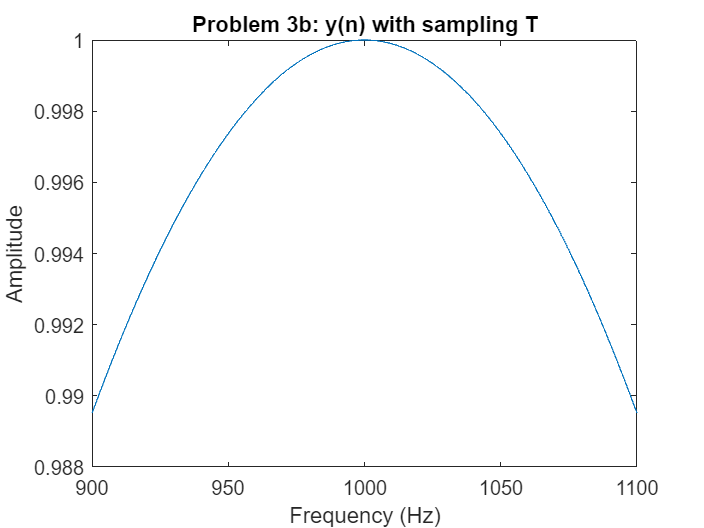

%Problem 3: part b
%show that it is possible to obtain yn by sampling xat with period T = 4ms.

T = 0.04; %ms
ts = 0:1/T:1;

Fs = 2500; %this is the sampling rate from the A/D converter
Ts = 1/Fs; n = round(Ts*Fs);
f_low = 900; f_high = 1100;

% Define the frequency range
F = linspace(f_low, f_high, 1000);

% Create a bandlimited function using the sinc function
xtn = sinc((F - 1000) / (Fs/2));

% Plot the bandlimited function
plot(F, xtn);
title('Problem 3b: y(n) with sampling T');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

## Problem 4 

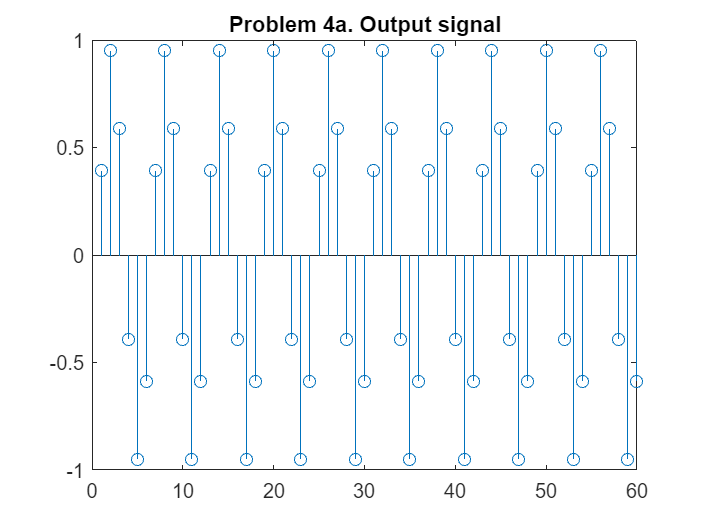

%plot the signals and corresponding spectra for rational sampling rate
%conversion. Assume that the spectrum of the input signal xn occupies the
%entire range -pi <= wx <= pi.

%Part a: I/D = 5/3
%for this problem, I am going to use a sign function to make it easy to
%display the difference
n = 0:99; %sampling area
xn = sin(0.2*pi*n); %sample signal
I = 5; D = 3;
%compute the output signal
m = 0:I/D: (length(xn)*I/D -1);
ym = interp1(1:length(xn), xn, m);
% Plot the input signal and its spectrum
stem(n, ym);
title("Problem 4a. Output signal")

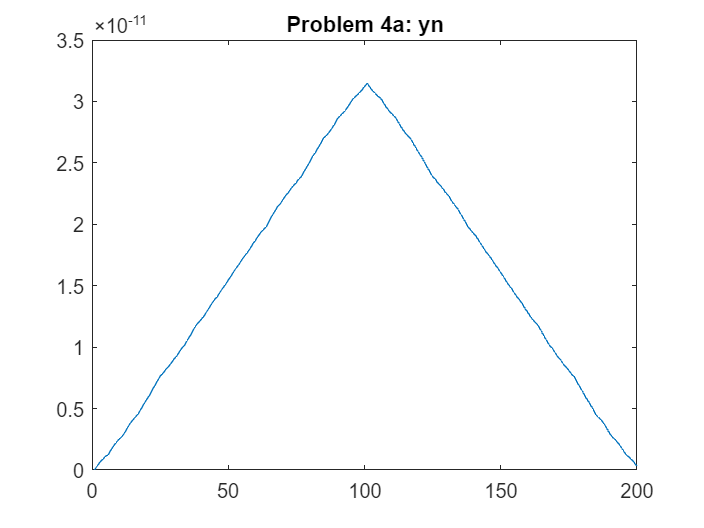

plot(abs(yn))
title("Problem 4a: yn")

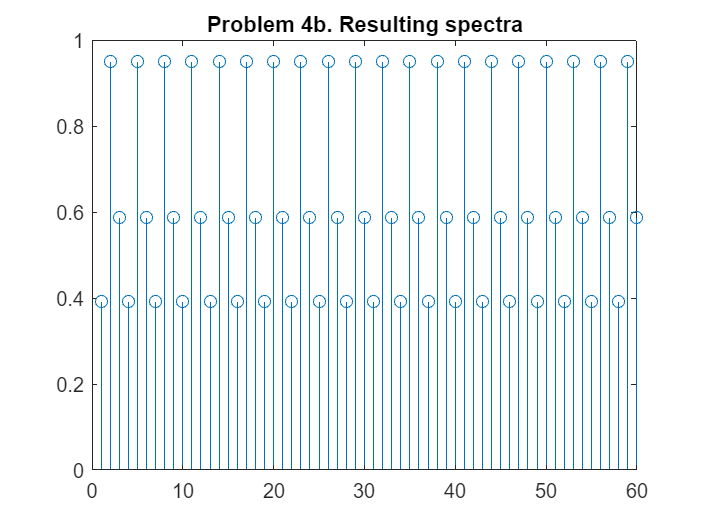

%partb: I/D = 3/5
%now, using the same exact function xn because it is simple, as well as the
%n sample size as well.

Ib = 3;
Db = 5;

% Compute the output signal y(m) based on the I/D ratio now
m2 = 0:I/D:(length(xn) * I / D - 1);
ym2 = interp1(1:length(xn), xn, m2);

%now to plot
stem(n, ym2);
title("Problem 4b. Resulting yn")

stem(n, abs(ym2));
title("Problem 4b. Resulting spectra")

## Problem 5

%part a: using kaiser windows, how many filter coefficients do we need?

% Filter specifications
Fs_original = 2048;     % Original sampling frequency
Fs_target = 64;         % Target sampling frequency
Fpass = 30;             % Passband frequency
Fstop = 32;             % Stopband frequency
Apass = 0.01;           % Passband deviation
Astop = 80;             % Stopband deviation

% Calculate normalized frequencies
normalized_Fpass = Fpass / Fs_original;
normalized_Fstop = Fstop / Fs_original;

% Calculate transition width
delta_f = (normalized_Fstop - normalized_Fpass) / 2;

% Kaiser window design parameters
beta = 5;   % Adjust as needed

% Calculate filter length
N = ceil((Astop - 7.95) / (2.285 * delta_f));

% Design the FIR filter using the Kaiser window
fir_filter = fir1(N, normalized_Fpass, 'low', kaiser(N+1, beta));

% Display the filter coefficients
disp('Filter Coefficients:');

Filter Coefficients:


disp(fir_filter);

  Columns 1 through 3,276

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   

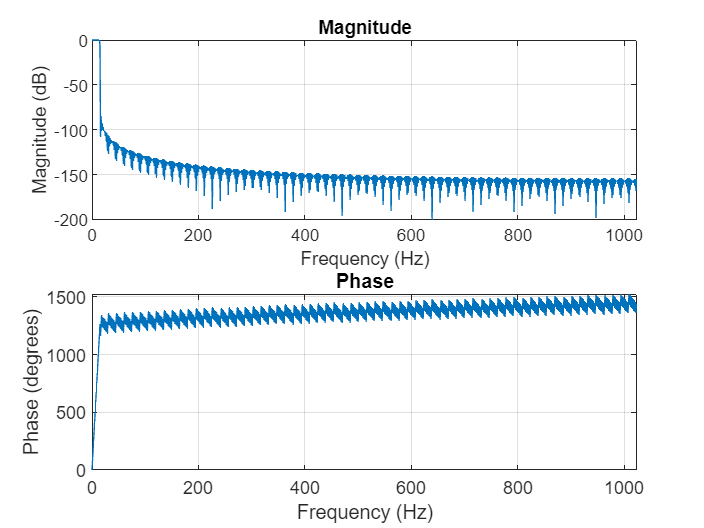


% Plot the frequency response of the filter
freqz(fir_filter, 1, 1024, Fs_original);

%Part b: parks macclellan method
% Design the FIR filter using Parks-McClellan method
filter_order = 80;  % Adjust as needed
equi_ripple = [Apass, Astop, Apass];  % Passband, Stopband, Passband

% Design the filter using Parks-McClellan algorithm
fir_filter = firpm(filter_order, [0, normalized_Fpass, normalized_Fstop, 1], [1, 1, 0, 0], equi_ripple);

Error using firpminit
There should be one weight per band.

Error in firpm (line 139)
[nfilt,ff,grid,des,wt,ftype,sign_val,hilbert,neg] = firpminit(order, ff, aa, varargin{:});


% Display the number of filter coefficients
disp(['Number of Filter Coefficients (Filter Length): ', num2str(filter_order + 1)]);

% Display the filter coefficients
disp('Filter Coefficients:');
disp(fir_filter);

% Plot the frequency response of the filter
freqz(fir_filter, 1, 1024, Fs_original);

%Part c: the suitability of one state decimator for the case:
% based on run time, the lower the filter coefficients is better for performance and
% being able to get more accurate results than waiting.

## Reference Functions

function hd = ideal_lp(wc, M); 
% Ideal LowPass filter computation 
% -------------------------------- 
% [hd] = ideal_lp(wc,M) 
% hd = ideal impulse response between 0 to M-1 
% wc = cutoff frequency in radians 
% M = length of the ideal filter
%
L = (M-1)/2; n = [0:1:(M-1)]; 
m = n - L; fc2 = wc/pi; hd = fc2*sinc(fc2*m); 
end